# kgme - single fish

## load data structure

IN LAB

load("/Volumes/Elements/rkg.mat");
%load("/Users/eric/Documents/MATLAB/rkg.mat");
%addpath('/Users/eric/SparkleShare/github.com/FishCodeGH/Gallman/');

## save data structure

IN LAB

save("/Users/eric/Documents/MATLAB/rkg.mat", "rkg", '-v7.3');
save("/Volumes/Elements/rkg.mat", 'rkg', '-v7.3');
save("/Volumes/My Book/Gallman/rkg.mat", 'rkg', '-v7.3');

AT HOME

save("/Users/kathryngallman/Documents/MATLAB/rkgbackup.mat", "rkg");
save("/Volumes/Elements/rkg.mat", 'rkg');

## reference raw data folder and asign k value

%raw data files live on the MyBook. Thankfully... ugh.
cd("/Volumes/Elements/Gallman/44LD/Frank4LD-April-26-2022-D/");
k = 141;

k = 1      4:4 LD        Sandwiches-Eigen04-Jan-24-2021-B

k = 2      4:4 LD        Olaf-Eigen04-Jan-24-2021-C

k = 3      48:48 LD    Social-Eigen48-Nov-22-2020-A

k = 4      48:48 LD    Social2-Eigen48-Nov-22-2020-B

k = 5      48:48 LD     Unsocial-Eigen48-Nov-22-2020-C

k = 6      10:10 LD     Eugene - Eigen10-05-Oct-2020-A

k = 7      10:10 LD     Ralf - Eigen10-05-Oct-2020-B - Eric this is so low amp that i need help... weirdly looks ok for sumfft but not obwamp

k = 8       6:6 LD        Eugene - Eigen6-12-Oct-2020-A

k = 9       6:6 LD        Ralf-Eigen6-12-Oct-2020-B

k = 10     24:24 LD    Ralf-Eigen24-Oct-30-2020-B

k = 11     24:24 LD    Sandwiches-Eigen24-Oct-20-2020-C (only really one full subjective day) - maybe add to hourdays

k = 12     12:12 LD    Large small - LigSm-14-Dece-2020-A

k = 13     12:12 LD    Milo - Milo20Dec20200-B    *need to fix feeding times, currently empty (originally set to combine after DarkLarge)

k = 14     12:12 LD    Green12-14Dec2020-C

k = 15      %changing from kg to 12:12 LD    DarkLarge -DkLrg12-12Dec2020-B    dying fish

k = 16     12:12 LD     Milo - Eigen12-Jan-12-2021-B

k = 17     12:12 LD     Potts - Eigen12-Jan-2021-C (second fish frequency)

k = 18      5:5 LD        Ralf -Eigen5-Nov-8-2020-B

k = 19      5:5 LD        Ralf -Eigen5-Nov-8-2020-B -different poweridx than 18

k = 20      5:5 LD        Sandwiches-Eigen5-Nov-8-2020-C

k = 21     12:12 LD      Pepper - Eigen12-Jan-2021-C (first fish frequency)

k = 22    empty

k = 23     12:12 LD      Eigen12-Jan-12-2021-A

k = 24      5:5 LD         Sandwiches-Eigen5-Nov-8-2020-C - different poweridx than k = 20

k = 25      8:8 LD         Polka08-March-16-2021-A

k = 26      8:8 LD         Dott8-March-16-2021-B

k = 27      8:8 LD         Weeny8-March-23-2021-C

k = 28      13:13 LD     Weeny13-March-31-2021-C

k = 29      13:13 LD     Polka13-March-31-2021-A

k = 30      13:13 LD     Dott13-March-31-2021-B

k = 31       %repeat of k = 28 in kg...

k = 32        %kg data not worth it

k = 33        6:6 LD    Dott06-April-17-2021-B

k = 34        6:6 LD    Weeny6-April-17-2021-C

k = 35        8:8 LD    Eugene: Eigen-28-Sept-2020-A

k = 36        8:8 LD    Ralf: Eigen28Sept2020-B

k = 37        20:20 LD    Bikini20-May-07-2021-A     - may need to re-normalize. large amplitude range in data

k = 38        20:20 LD    Dott20-May-07-2021-B

k = 39        20:20 LD    Itsy20-May-07-2021-C    - huge amplitude increase at end...

k = 40        20:20 LD    Dott20-May-02-2021-B

k = 41        16:16 LD    Dott16-May-2021-B

k = 42        16:16 LD    Bikini16-May-18-2021-A     

k = 43         16:16 LD    Itsy16-May-18-2021-C    

k = 44        48:48 LD    Bikini48-May-21-2021-A   

k = 45        48:48 LD    Dott48-May-21-2021-B - only channel 2 data is good

k = 46        48:48 LD    Yellow48-May-24-2021-C    only channel 1 data is good for entire timcont

k = 47        12:12  LD   Bikini12-June-29-2021-A     second half temp modulation (maybe divide into two)

k = 48        12:12 LD temp Bikini12-July-13-2021-A - all over the place data

k = 49        48L48 LDtemp    Bikini48-July-19-2021-A - funky data

k = 50        XXtemp - mostly dark BikiniXX-July-30-2021-A    ONLY USE CH1

k = 51        XXtemp - mostly dark MaryXX-Aug-1-2021-C    ONLY USE CH1

k = 52        XXtemp  -mostly dark    BikiniXX-Aug-10-2021-A    Ch1 still far superior

k = 53        XXtemp -mostly dark    BaltoXX-Aug-10-2021-C  ONLY USE CH1

k = 54        4:4 LD    Cheshire04-Aug-21-2021-A    Ch1 is better

k = 55        4:4 LD    Balto04-Aug-31-2021-C    Ch1 better

k = 56        24:24 LD    Cheshire24-Sept-3-2021-A     USE CH1

k = 57        24:24 LD    Balto24-Sept-3-2021-C    1 st half Needs to be multiplied by gain step... saving for later

k = 58        5:5 LD    Cheshire05-Sept-13-2021-A        USE CH1

k = 59        5:5 LD    Balto05-Sept-13-2021-C        USE CH1 (heavily Removed to control for weird amplification effect)

k = 60        10:10    Cheshire10-Sept-24-2021-A    USE CH1    - needs to be adjusted aroung 100 hours - left for later

fucking sparkle... bring laptop toms

k = 61        10:10 LD    Balto10-Sept-24-2021-C

k = 62     empty

k = 63        24:24 LD    Lizzy24-Oct-15-2021-C

k = 64        12:12 LD    Ferdie12-Oct-20-2021-A

k = 65        12:12 LD    Lydia12-Oct-21-2021-C

k = 66        12:12 LD    Cheshire12-Oct-20-2021-D

k = 67        12:12 LD    Paco12-Oct-20-2021-E

k = 68        124 LD    Cheshire124-Nov-03-2021-D

k = 69        124 LD    Paco124-Nov-03-2021-E

k = 70        124 LD    Ferdie124-Nov-03-2021-A

k = 71        124 LD    Lydia124-Nov-04-2021-C

k = 72        124 LD    Cheshire124-Nov-18-2021-D

k = 73        124 LD    Ferdie124-Nov-18-2021-A

fucking sparkle... bring laptop toms

k = 74        124 LD     Lydia124-Nov-18-2021-C    USE CH1

k = 75        124 LD     Paco124-Nov-18-2021-E    barely any dark triggers - probs don't use

k = 76        24:24 LD    Lydia24-Dec-05-2021-C    a bit multimodal

k = 77        24:24 LD     Mama24-Dec-09-2021-A    skipped redo for now - needs to be normalized in chunks? electrode bumped?

k = 78        24:24 LD    Pedro24-Dec-05-2021-E    USE CH1

k = 79        24:24 LD    Cheshire24-Dec-05-2021-D    

k = 80        48:48 LD    Mama48-Dec-17-2021-A    need to fix luz

k = 81        48:48 LD    Lydia48-Dec-17-2021-C    weird amp increase at beginning - confused sychrony?

k = 82        48:48 LD    Cheshire48-Dec-17-2021-D

k = 83        48:48 LD    Pedro48-Dec-17-2021-E    FIXED FREQY REMOVER

k = 84        12:12 LD    Cheshire12-Jan-04-2022-D    USE CH1

k = 85        12:12 LD    Lydia12-Jan-04-2022-C

k = 86        10:10 LD    Cheshire10-Jan-07-2022-D    USE CH1 

k = 87        10:10 LD    Greenie10-Jan-07-2022-A    USE CH2

k = 88        10:10 LD    Lydia10-Jan-07-2022-C

k = 89        10:10 LD    Pablo10-Jan-07-2022-E        USE CH1

k = 90        20:20 LD    Cheshire20-Jan-17-2022-D    temperature changes - 2nd half

k = 91        20:20 LD    Greenie20-Jan-17-2022-A    need to fix ch1 chunk before outlier removal... left for later

k = 92        20:20 LD    Lydia20-Jan-17-2022-C    USE CH1    very weirdly shaped data - kinda multimodal

k = 93        20:20 LD    Pablo20-Jan-17-2022-E    USE CH1    need to gain adjust... TEMP CHANGES W/ LIGHTS 2ND HALF

k = 94        13:13 LD    Weeny13-March-31-2021-C    USE CH1    should split into two power idxs, maybe three gain adjustment chunks

k = 95

REPEATS poweridx, etc

k = 101

k = 102        48:48 LD Cheshire48LDtemp-Jan-27-2022-D    USE CH1 single 48 hour day

k = 103        48:48 LD TEMP    Ginumbo48temp-Feb-14-2022-C    USE CH1    forgot about temp tim lines til here - will need to redo labels for previous

k = 104        48:48 LD TEMP    Greenie48LDtemp-Jan-27-2022-A    NEEDS TO BE CLEANED UP -saved for later

k = 105        48:48 LD TEMP     LYDIA48LDTemp-Jan-27-2022-C    TEMP TIMS NEED HELP

k = 106        48:48 LD    Pablo48LDtemp-Jan-27-2022-E    needs to be renormalized... somehow. GIANT FILE    

k = 107    48:48 LD         Rose48LDtemp-Feb-05-2022-D

k = 108    freerun LL  TEMP  GinumboXXtemp-March-10-2022-C

k = 109    freerun LL   TEMP  MikaXXtemp-March-10-2022-A     USE CH2

k = 110    freerun LL    PicassoLL-Feb-27-2022-E    USE CH2?

k = 111    REPEAT

k = 112    12:12 LD to freerun LL    Rose12-Feb-23-2022-D    USE CH1

k = 113    Ginumbo12Ldpulse-March-15-2022-C    USE CH1 weird frequency thing around 160hrs

k = 114    Mika12Ldpulse-March-15-2022-A    needs some gain adjustment around 165.184

k = 115    Picasso12Ldpulse-March-15-2022-E    needs more gain adjustment love

k = 116    repeat

k = 117    repeat

k = 118    repeat - power idx

k = 119    repeat

k = 120    repeat

k = 121    Ginumbo6Ldpulse-March-22-2022-C    USE CH1

k = 122    empty?

k = 123    Mika6Ldpulse-March-22-2022-A

k = 124    PicassoLdpulse-March-22-2022-E    no luz?

k = 125    Rose6Ldupulse-March-22-2022-D    USE CH1

k = 126    Rein6DlpulseSignal-April-9-2022-C - skipped for now - need to change sig analysis code

k = 127    Mika6Dlpulse-April-9-2022-E    USE CH1

k = 128    Rose6Dlpuse-April-9-2022-D    skipped for now - need to change sig analysis code

k = 129    Rose13LD-March-31-2022-D    USE CH1

k = 130    Ginumbo13JAR-March-31-2022-C    SKIPPED

k = 131    Mika13LD-March-31-2022-A    USE CH1

k = 132    Mika13LD-April-2-2022-E    NEEDS MULTIPLE GAIN ADJUSTMENTS

k = 133    Mika13LD-March-31-2022-RigAvsRigE    SKIPPED

k = 134    REPEAT

k = 135    Mika5LD-April-13-2022-E    USE CH1

k = 136    Rein5LD-April-13-2022-C

k = 137    Rose5LD-April-13-2022-D    needs gain adjustment

k = 138    Rose5LD-April-13-2022-D    needs gain adjustment

k = 139    Mika12Dlpulse-April-18-2022-E    needs gain adjustment

k = 140    Reing 12Dlpuse sig    SKIPPED

k = 141

## generate amplitude data

rkg(k).e = KatieAssembler('Eigen*',  23);

%rkg(k).e = KatieAssembler('Eigen*',  22); %really old data
%kg(k).e = KatieAssembler('Eigen*', 40000, 24); %Katie is bad at typing...

rkg(k).e = KatieAssemblerSig('Eigen*', 40000, 23, 300);

## initial plotter

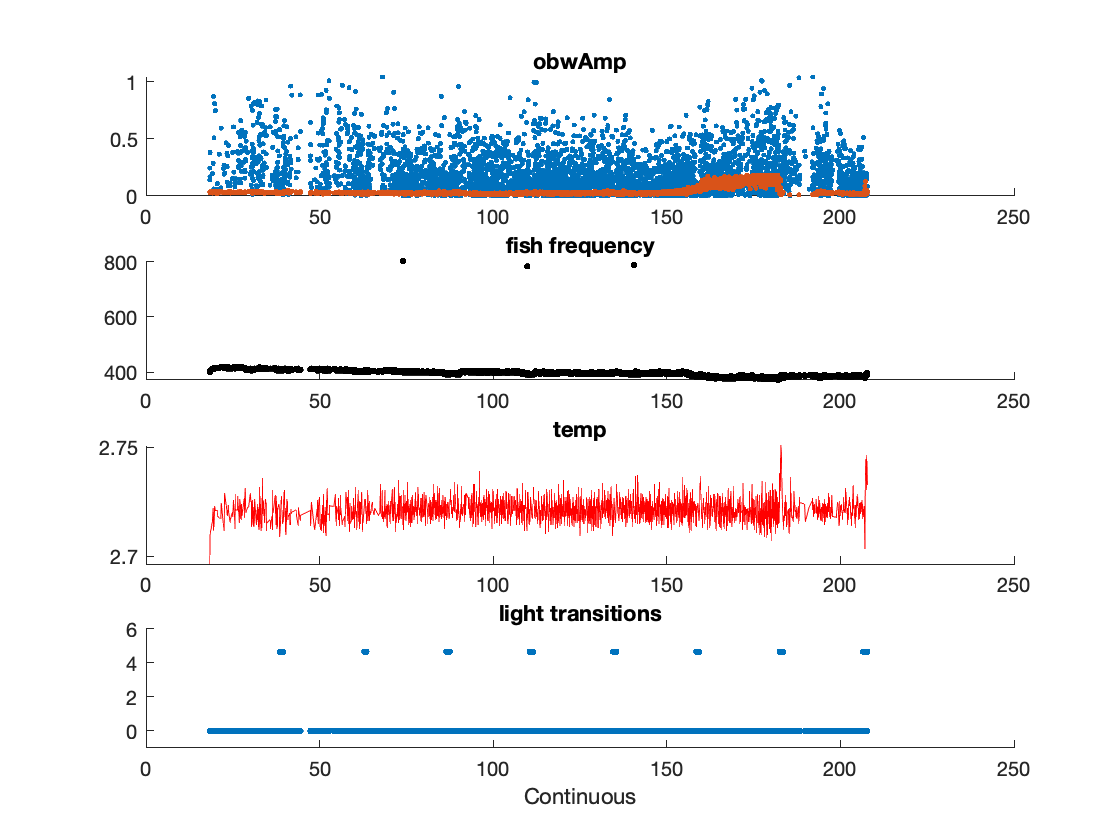

k_initialplotter(rkg(k));

#### Remove outliers

Must be redone after trimming

rkg(k).idx = KatieRemover(rkg(k).e);

## Label

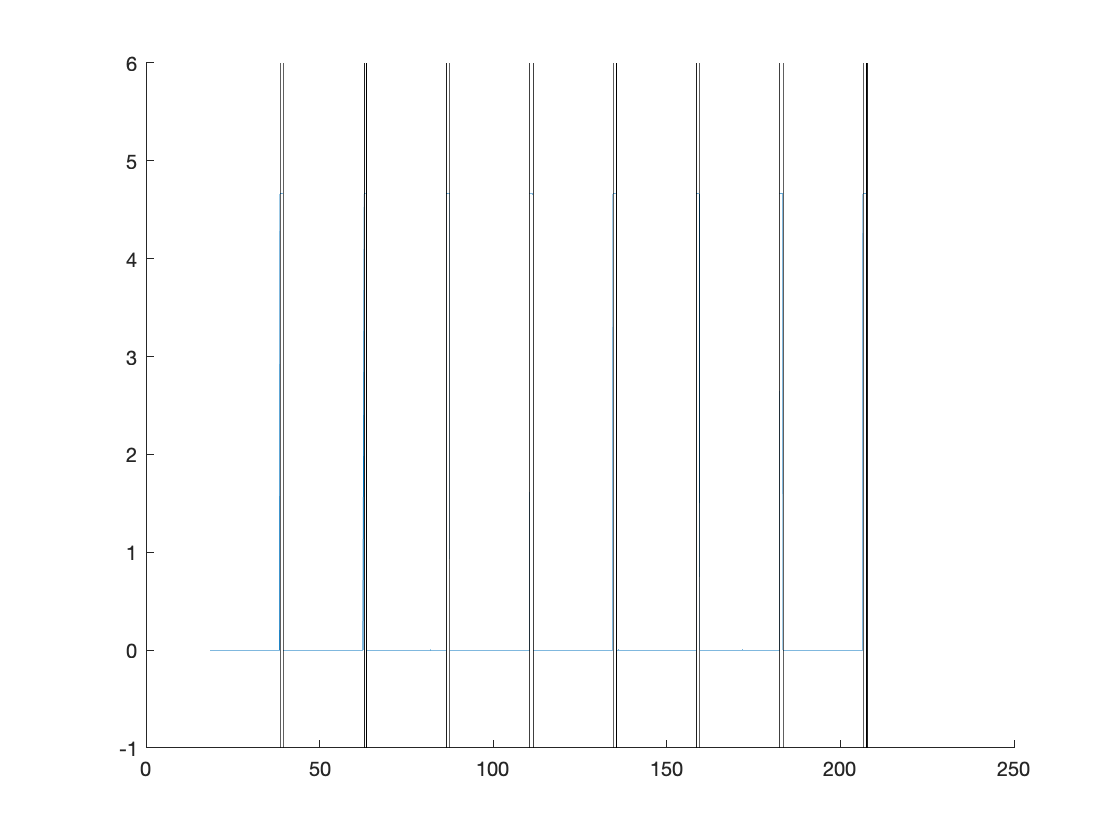

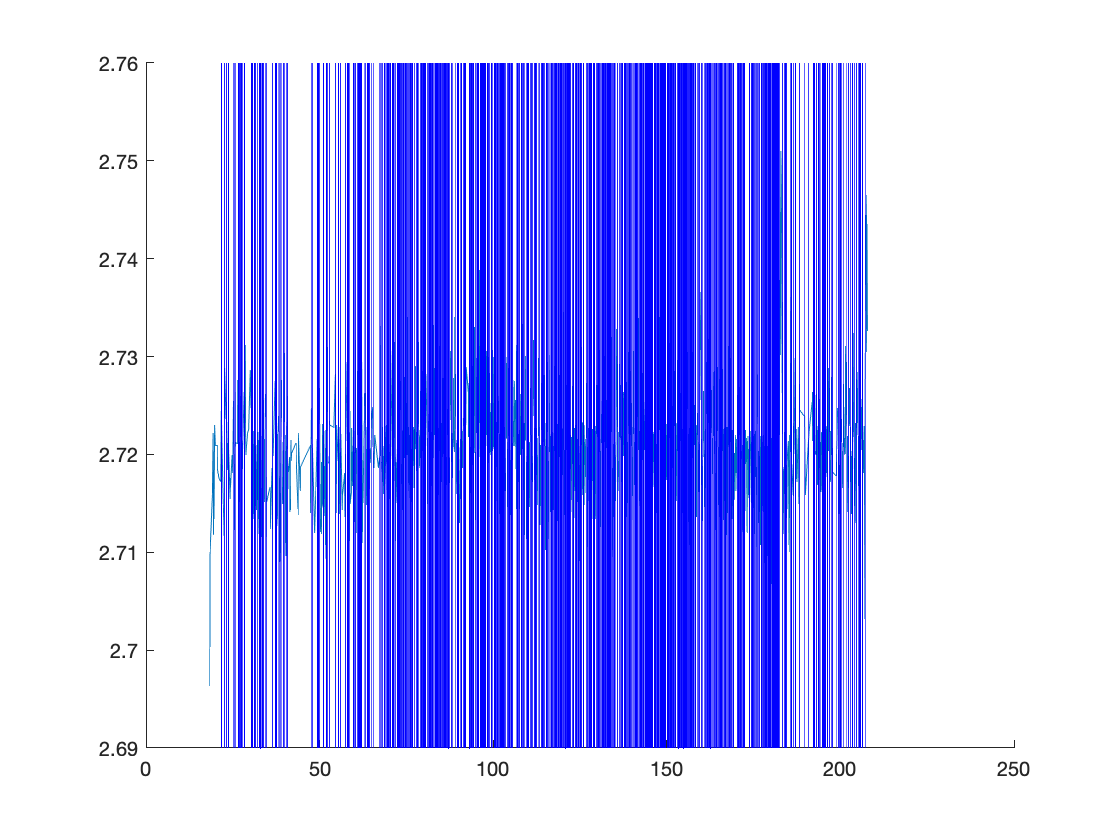

rkg(k).info = KatieTempLabeler(rkg(k).e);

## edits

#### frequency trimming

Do before outlier removal

extra step in case of instant clicking regret...

tempdata = KatieFreakyFreqRemover(rkg(k).e)

tempdata = 1×2 struct array with fields:
    s


rkg(k).e = tempdata;

#### trim data

extra step in case of instant clicking regret...

tempdata = KatieTrimmer(rkg(k).e);

if before was on purpose 

rkg(k).e = tempdata;


for channel = 1

    fudgeidx = find([rkg(k).e(channel).s.timcont]/3600 > 21.22 &  [rkg(k).e(channel).s.timcont]/3600 < 38.5);
    for kk = 1:length(fudgeidx)
    
        rkg(k).e(channel).s(fudgeidx(kk)).sumfftAmp = [rkg(k).e(channel).s(fudgeidx(kk)).sumfftAmp]*4;
        rkg(k).e(channel).s(fudgeidx(kk)).obwAmp = [rkg(k).e(channel).s(fudgeidx(kk)).obwAmp]*4;
    
    end
end